Prof. Dr. Ralf Hielscher 

Erik Wünsche

TU Bergakademie Freiberg

Summer Semester 2025

# Mathematical Image Processing - Exercise Sheet 6

Download the zip file` sheet6.zip `with the images for the following tasks from OPAL. Please make sure your current working directory (Working directory/Current Folder) in MATLAB matches the folder where the exercises are located.

**Important Tips:**

- Use **Ctrl+Enter** to run a section.

- Use **Ctrl+Alt+Enter** to insert section breaks.

- Use **F9** to execute highlighted code in the command window.

#### Exercise 1: (Discrete Wavelet Transform of an Image)

Load the image `cameraman.tif `and plot it.

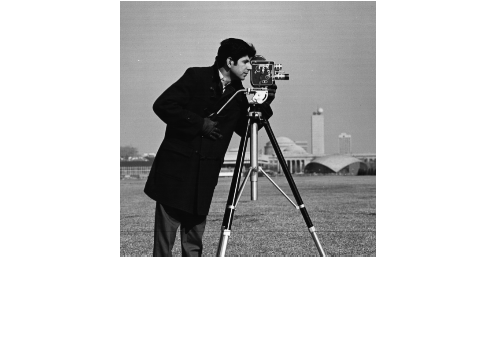

% Load image
img = imread('cameraman.tif');
img = im2double(img);
figure
imshow(img)

Perform a 5-level discrete wavelet decomposition using the Haar wavelet. 

% Perform 5-level discrete wavelet decomposition using Haar wavelet
[coeffs, sizes] = wavedec2(img, 5, 'haar');

We can look at the detail- and approximation-coefficients by using the` detcoef2 `and` appcoef2 `commands.

% Extract detail and approximation coefficients at level n
for n=1:5

  [H{n}, V{n}, D{n}] = detcoef2('all', coeffs, sizes, n);
  A{n} = appcoef2(coeffs,sizes,'haar',n);

  % For better Visualization we normalize the detail and approximation matrices to [0,1].
  A{n} = A{n}./max(A{n}(:));
  H{n} = (H{n}-min(H{n}(:)))./(max(H{n}(:))-min(H{n}(:)));
  V{n} = (V{n}-min(V{n}(:)))./(max(V{n}(:))-min(V{n}(:)));
  D{n} = (D{n}-min(D{n}(:)))./(max(D{n}(:))-min(D{n}(:)));

end

In the following we want to visualize the wavelet coefficients of level 1.

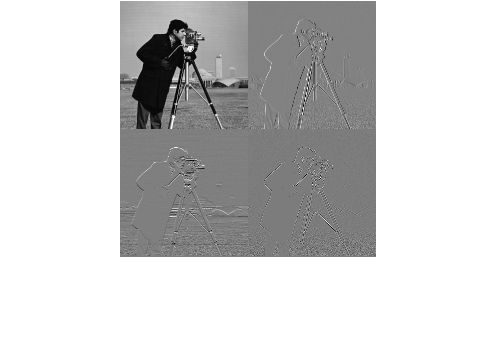

% Visualize coefficients at level 1
I{1} = [ A{1} , V{1} ; H{1} , D{1} ];
imshow(I{1})

In a second step we visualize the coefficients up to a certain level.

Coefficients up to Level 2


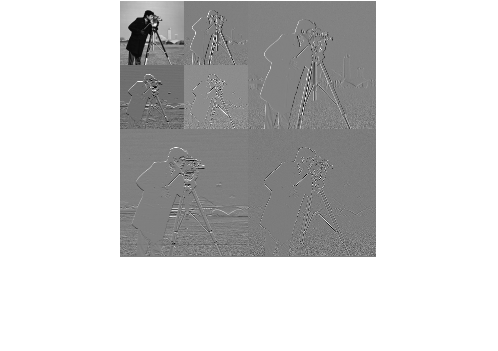

Coefficients up to Level 3


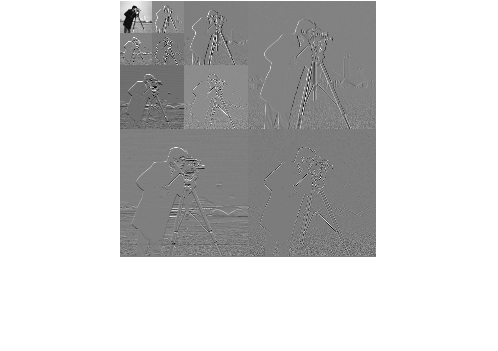

Coefficients up to Level 4


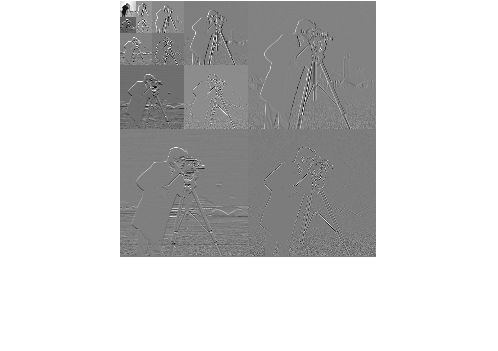

Coefficients up to Level 5


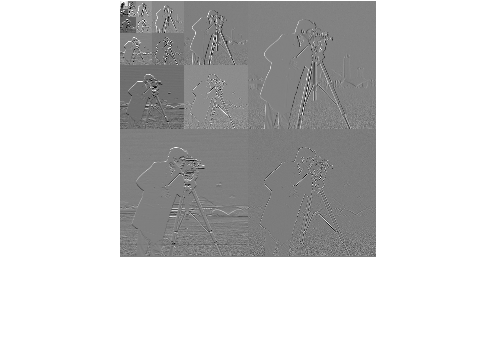

for n=2:5
  I{n} = I{n-1};
  I{n}(1:sizes(end+1-n,1) ,1:sizes(end+1-n,2)) = [ A{n} , V{n} ; H{n} , D{n} ];
  figure
  disp(['Coefficients up to Level ',num2str(n)])
  imshow(I{n})
end

Answer the following questions:

- What is the meaning of the levels?

- What do you observe in the approximation coefficients?

- Where do the detail coefficients have high values?

#### Exercise 2: (Different Wavelet Types)

Take a look on the different Wavelet types:

- Daubechies-Wavelet of order 1   (Haar-Wavelet)

- Daubechies-Wavelet of order 2

- Daubechies-Wavelet of order 4

- Daubechies-Wavelet of order 8

Note that higher orders mean that the wavelets are smoother.

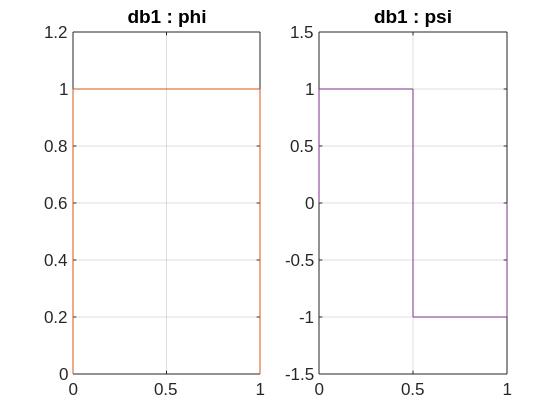

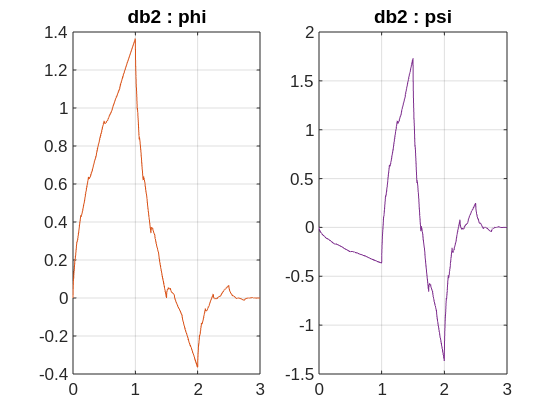

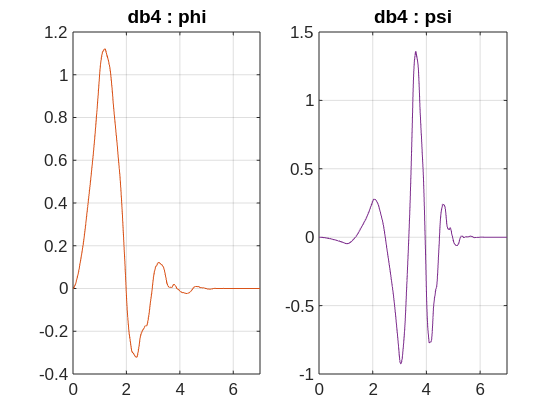

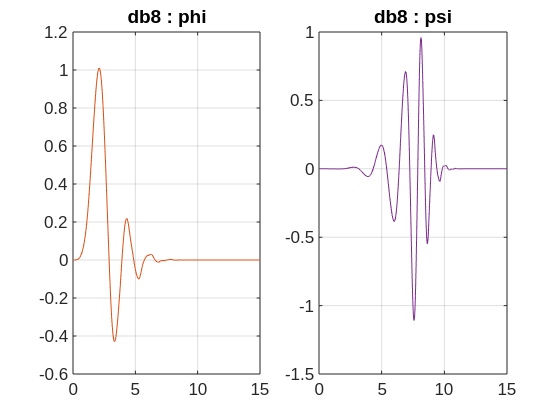

wavelets = {'db1', 'db2', 'db4', 'db8'}; % wavelet names

for i = 1:length(wavelets)
    figure
    [phi, psi, x] = wavefun(wavelets{i}, 15,'plot' );
end

#### Exercise 3: (Wavelet-Based Edge Detection)

In exercise 1, we allready saw that the Wavelet detail coefficients highlight where sharp intensity changes (edges) occur. 

Hence we use them to determine edges.

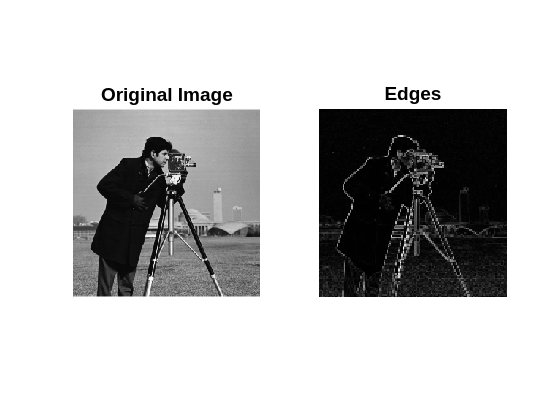

% Load image
img = imread('cameraman.tif');
img = im2double(img);

% 1-level Haar wavelet decomposition
[coeffs, sizes] = wavedec2(img, 1, 'haar');

% Extract horizontal, vertical, and diagonal detail coefficients
[H, V, D] = detcoef2('all', coeffs, sizes, 1);

% Compute edge strength as combined magnitude
edges = sqrt(H.^2 + V.^2 + D.^2);

% Normalize for display
edges = edges / max(edges(:));

% Visualization
figure;
subplot(1,2,1), imshow(img), title('Original Image');
subplot(1,2,2), imshow(edges, []), title('Edges');

#### **Exercise 4: (Wavelet-Based Image Compression)**

First we load the image` cameraman.tif`.

% Load image and add Gaussian noise
img = imread('cameraman.tif');
img = im2double(img);

Now we want to use the wavelet transform to compress this image. 

Therefore we compute the wavelet decomposition and perform tresholding on the detail coefficients.

% Haar wavelet decomposition
level = 5;
[coeffs, sizes] = wavedec2(img, level, 'haar');

% Tresholding
first = prod(sizes(2,:))+1;
c = coeffs(first+1:length(coeffs));
c( abs(c) < 0.01 * max(abs(c)) ) = 0;
coeffs(first+1:length(coeffs)) = c;

And we reconstruct the image from the modified wavelet coefficients.

% Reconstruct image
img_reconstructed = waverec2(coeffs, sizes, 'haar');

At the end, we visualize the noisy, and denoised images side by side.

How effective is the wavelet denoising? Are edges preserved after denoising?

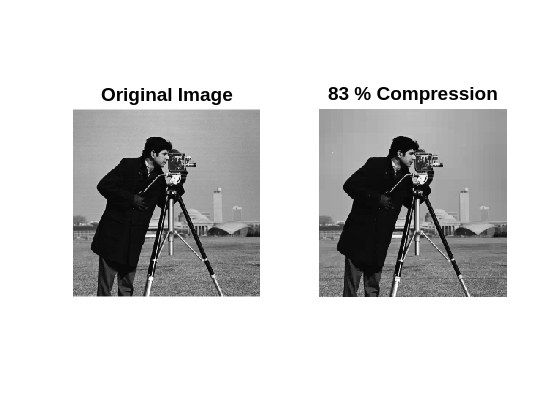

% Compression factor
cf = sum(coeffs==0) / numel(coeffs);

% Visualization
figure;
subplot(1,2,1), imshow(img), title('Original Image');
subplot(1,2,2), imshow(img_reconstructed), title(sprintf('%.f %% Compression', cf*100));

#### Exercise 5: (Image Denoising with Wavelets)

First we add Gaussian noise with zero mean and variance 0.01 to the image` cameraman.tif`.

% Load image and add Gaussian noise
img = imread('cameraman.tif');
img = im2double(img);
img = imnoise(img, 'gaussian', 0, 0.001);

Now we want to use the wavelet transform to denoise this image. 

Therefore we compute the wavelet decomposition up to level 5.

% Haar wavelet decomposition
level = 5;
[coeffs, sizes] = wavedec2(img, level, 'haar');

The idea is to perform tresholding on the detail coefficients of every single level.

We choose the treshold sensitive to the level as $t = \frac{c}{2^j} \cdot \max\{ \text{level coeffis}\}$ with some constant $c$.

for j = 1:level
  first = prod(sizes(end-j,:))+1;
  last = prod(sizes(end-j+1,:));
  c = coeffs(first:last);
  t = 0.3 / 2^j * max(abs(c));
  c( abs(c) < t ) = 0;
  coeffs(first:last) = c;
end

And we reconstruct the image from the modified wavelet coefficients.

% Reconstruct image
denoised_img = waverec2(coeffs, sizes, 'haar');

At the end, we visualize the noisy, and denoised images side by side.

How effective is the wavelet denoising? Are edges preserved after denoising?

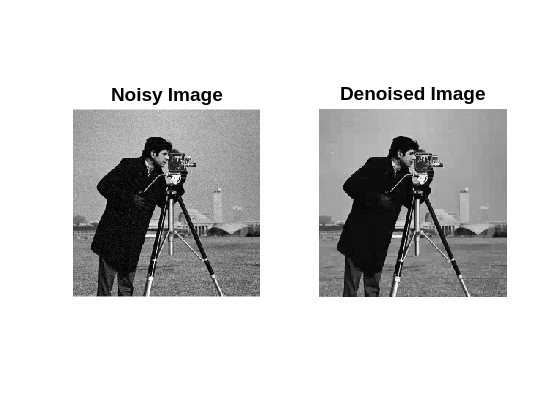

% Visualization
figure
subplot(1,2,1), imshow(img), title('Noisy Image');
subplot(1,2,2), imshow(denoised_img), title('Denoised Image');